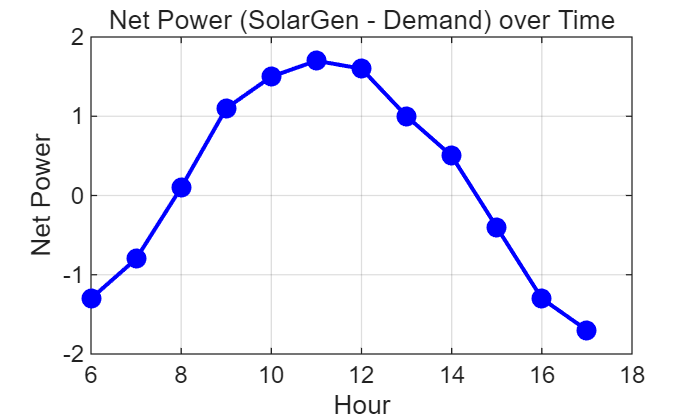

% 1번 문제 시작
clear; clc;

% (a) Hour, SolarGen, Demand, Battery 값을 각각 '열벡터'로 생성
% 행벡터를 만든 뒤 전치 연산자(')를 사용하여 열벡터로 변환합니다.
Hour = [6, 7, 8, 9, 10, 11, 12, 13, 14, 15, 16, 17]';
SolarGen = [0.5, 1.2, 2.4, 3.8, 4.6, 5.1, 5.4, 5.0, 4.2, 3.0, 1.7, 0.8]';
Demand = [1.8, 2.0, 2.3, 2.7, 3.1, 3.4, 3.8, 4.0, 3.7, 3.4, 3.0, 2.5]';
Battery = [3.2, 3.0, 3.1, 3.8, 4.5, 5.2, 5.9, 6.3, 6.5, 6.1, 5.4, 4.7]';

% (b) 네 열벡터를 결합하여 12x4 숫자 행렬 A 생성
A = [Hour, SolarGen, Demand, Battery];

% (c) writematrix를 사용하여 숫자 행렬 A를 solar_system.txt 파일로 저장
writematrix(A, 'solar_system.txt');

% (d) load 함수를 사용하여 파일을 불러오고 숫자 행렬 B에 저장
B = load('solar_system.txt');

% (e) 숫자 행렬 B의 각 열을 추출하여 새 변수로 저장 (콜론 : 연산자 사용)
hour = B(:, 1);
solar = B(:, 2);
demand = B(:, 3);
battery = B(:, 4);

% (f) solar에서 demand를 뺀 값을 netPower라는 열벡터로 저장
netPower = solar - demand;

% (g) hour를 x축, netPower를 y축으로 하여 선 그래프 그리기
figure;
plot(hour, netPower, 'bo-', 'LineWidth', 1.5, 'MarkerFaceColor', 'b');
title('Net Power (SolarGen - Demand) over Time');
xlabel('Hour');
ylabel('Net Power');
grid on;


% -------------------- 결과 출력 확인용 --------------------
disp('[(b) 생성된 숫자 행렬 A]');

[(b) 생성된 숫자 행렬 A]


disp(A);

    6.0000    0.5000    1.8000    3.2000
    7.0000    1.2000    2.0000    3.0000
    8.0000    2.4000    2.3000    3.1000
    9.0000    3.8000    2.7000    3.8000
   10.0000    4.6000    3.1000    4.5000
   11.0000    5.1000    3.4000    5.2000
   12.0000    5.4000    3.8000    5.9000
   13.0000    5.0000    4.0000    6.3000
   14.0000    4.2000    3.7000    6.5000
   15.0000    3.0000    3.4000    6.1000
   16.0000    1.7000    3.0000    5.4000
   17.0000    0.8000    2.5000    4.7000




disp('[(f) 계산된 netPower 열벡터]');

[(f) 계산된 netPower 열벡터]


disp(netPower);

   -1.3000
   -0.8000
    0.1000
    1.1000
    1.5000
    1.7000
    1.6000
    1.0000
    0.5000
   -0.4000
   -1.3000
   -1.7000



% 2번 문제 시작
clear; clc;

% (a) 데이터를 숫자 행렬 D로 생성
D = [1, 2.1, 8,  12;
     2, 3.4, 13, 19;
     3, 1.8, 7,  10;
     4, 5.2, 21, 31;
     5, 4.7, 19, 28;
     6, 6.0, 25, 36;
     7, 3.1, 12, 18;
     8, 5.8, 24, 35];

% (b) writematrix를 사용하여 txt 파일로 저장한 뒤, load로 다시 불러오기
writematrix(D, 'drone_delivery.txt');
loaded_D = load('drone_delivery.txt');

% (c) 불러온 행렬에서 각 열을 변수로 추출
RouteID = loaded_D(:, 1);
DistanceKm = loaded_D(:, 2);
TimeMin = loaded_D(:, 3);
BatteryUsed = loaded_D(:, 4);

% (d) km/min 단위의 평균 속도 벡터 계산 
% 벡터 간의 나눗셈이므로 반드시 요소별 연산자(./)를 사용해야 합니다.
speed = DistanceKm ./ TimeMin;

% (e) 배터리 사용 효율 벡터 계산 (요소별 연산자 ./ 사용)
BatteryPerKm = BatteryUsed ./ DistanceKm;

% (f) BatteryPerKm > 6인 배송지만 추출하여 하나의 행렬로 출력
% 논리 인덱싱(Logical Indexing)을 활용하여 조건에 맞는 행만 필터링합니다.
idx = BatteryPerKm > 6; 
result_matrix = [RouteID(idx), DistanceKm(idx), BatteryPerKm(idx)];

% -------------------- 결과 출력 확인용 --------------------
disp('[(d) 평균 속도 벡터 (speed)]');

[(d) 평균 속도 벡터 (speed)]


disp(speed);

    0.2625
    0.2615
    0.2571
    0.2476
    0.2474
    0.2400
    0.2583
    0.2417




disp('[(e) 배터리 사용 효율 벡터 (BatteryPerKm)]');

[(e) 배터리 사용 효율 벡터 (BatteryPerKm)]


disp(BatteryPerKm);

    5.7143
    5.5882
    5.5556
    5.9615
    5.9574
    6.0000
    5.8065
    6.0345




disp('[(f) BatteryPerKm > 6인 배송지 행렬 (RouteID, Distance, BatteryPerKm)]');

[(f) BatteryPerKm > 6인 배송지 행렬 (RouteID, Distance, BatteryPerKm)]


disp('   [ID]     [Km]   [Battery/Km]');

   [ID]     [Km]   [Battery/Km]


disp(result_matrix);

    8.0000    5.8000    6.0345



% 3번 문제 시작
clear; clc;

% (a) Zone, Temp, Humidity, Light, CO2 변수 각각 생성 (열벡터 형태)
% 문자열 데이터인 Zone은 중괄호 {}를 사용해 셀 배열(Cell Array)이나 큰따옴표("") 문자열 배열로 만듭니다.
Zone = {'Z1'; 'Z2'; 'Z3'; 'Z4'; 'Z5'; 'Z6'; 'Z7'; 'Z8'};
Temp = [22.5; 24.1; 21.8; 25.3; 23.7; 26.0; 22.9; 24.8];
Humidity = [61; 58; 67; 55; 62; 53; 65; 57];
Light = [420; 460; 390; 520; 480; 550; 410; 500];
CO2 = [510; 540; 495; 610; 575; 640; 520; 600];

% (b) 위 변수들을 이용하여 table Farm 생성
Farm = table(Zone, Temp, Humidity, Light, CO2);

% (c) 식을 계산하여 Farm 테이블에 'EnvIndex'라는 새 변수(열) 추가
Farm.EnvIndex = 0.4 * Farm.Temp + 0.01 * Farm.Light + 0.02 * Farm.CO2;

% (d) EnvIndex >= 25인 구역만 논리 인덱싱을 통해 추출하여 HighEnv에 저장
% 행에는 조건식(EnvIndex >= 25)을 넣고, 열에는 콜론(:)을 넣어 모든 열을 가져옵니다.
HighEnv = Farm(Farm.EnvIndex >= 25, :);

% (e) HighEnv에서 특정 변수(열)만 소괄호 ()를 사용하여 table 형태로 추출 및 출력
% 열 이름들을 셀 배열 {} 형태로 묶어서 소괄호 안에 지정하면 원하는 열만 골라낼 수 있습니다.
result_table = HighEnv(:, {'Zone', 'Temp', 'Light', 'EnvIndex'});

% -------------------- 결과 출력 확인용 --------------------
disp('[(b), (c) 완성된 Farm table]');

[(b), (c) 완성된 Farm table]


disp(Farm);

     Zone     Temp    Humidity    Light    CO2    EnvIndex
    ______    ____    ________    _____    ___    ________

    {'Z1'}    22.5       61        420     510      23.4  
    {'Z2'}    24.1       58        460     540     25.04  
    {'Z3'}    21.8       67        390     495     22.52  
    {'Z4'}    25.3       55        520     610     27.52  
    {'Z5'}    23.7       62        480     575     25.78  
    {'Z6'}      26       53        550     640      28.7  
    {'Z7'}    22.9       65        410     520     23.66  
    {'Z8'}    24.8       57        500     600     26.92  




disp('[(d) EnvIndex >= 25인 HighEnv table]');

[(d) EnvIndex >= 25인 HighEnv table]


disp(HighEnv);

     Zone     Temp    Humidity    Light    CO2    EnvIndex
    ______    ____    ________    _____    ___    ________

    {'Z2'}    24.1       58        460     540     25.04  
    {'Z4'}    25.3       55        520     610     27.52  
    {'Z5'}    23.7       62        480     575     25.78  
    {'Z6'}      26       53        550     640      28.7  
    {'Z8'}    24.8       57        500     600     26.92  




disp('[(e) 소괄호()를 사용하여 특정 변수만 출력한 최종 결과]');

[(e) 소괄호()를 사용하여 특정 변수만 출력한 최종 결과]


disp(result_table);

     Zone     Temp    Light    EnvIndex
    ______    ____    _____    ________

    {'Z2'}    24.1     460      25.04  
    {'Z4'}    25.3     520      27.52  
    {'Z5'}    23.7     480      25.78  
    {'Z6'}      26     550       28.7  
    {'Z8'}    24.8     500      26.92  



% 4번 문제 시작
clear; clc;

% (a) 데이터를 table Factory로 생성
% 문자열 데이터(Machine)는 중괄호 {}를 사용해 셀 배열로 생성합니다.
Machine = {'M1'; 'M2'; 'M3'; 'M4'; 'M5'; 'M6'; 'M7'; 'M8'; 'M9'; 'M10'};
Vibration = [1.8; 2.4; 1.5; 3.1; 2.7; 1.9; 3.5; 2.2; 1.6; 2.9];
Temp = [68; 72; 65; 78; 74; 69; 82; 71; 66; 76];
Power = [4.5; 5.1; 4.2; 6.3; 5.7; 4.8; 6.8; 5.0; 4.4; 6.0];
Defect = [2; 5; 1; 8; 6; 3; 10; 4; 1; 7];

Factory = table(Machine, Vibration, Temp, Power, Defect);

% (b) RiskScore = Vibration * Temp / Power 를 계산하여 새 변수로 추가
% 벡터 간의 연산이므로 반드시 요소별 곱셈(.*)과 나눗셈(./)을 사용해야 합니다.
Factory.RiskScore = (Factory.Vibration .* Factory.Temp) ./ Factory.Power;

% (c) RiskScore >= 35 이면서 Defect >= 6 인 장비만 추출하여 RiskMachines에 저장
% 두 가지 조건을 동시에 만족해야 하므로 논리 연산자 AND(&)를 사용합니다.
RiskMachines = Factory(Factory.RiskScore >= 35 & Factory.Defect >= 6, :);

% (d) RiskMachines에서 Machine, RiskScore, Defect만 table 형태로 출력
% 소괄호 ()를 사용하여 table의 구조를 유지한 채로 원하는 열만 골라냅니다.
result_table = RiskMachines(:, {'Machine', 'RiskScore', 'Defect'});

% (e) writetable을 이용하여 전체 Factory table을 csv 파일로 저장
writetable(Factory, 'factory_risk.csv');

% -------------------- 결과 출력 확인용 --------------------
disp('[(b) RiskScore가 추가된 Factory table]');

[(b) RiskScore가 추가된 Factory table]


disp(Factory);

    Machine    Vibration    Temp    Power    Defect    RiskScore
    _______    _________    ____    _____    ______    _________

    {'M1' }       1.8        68      4.5        2         27.2  
    {'M2' }       2.4        72      5.1        5       33.882  
    {'M3' }       1.5        65      4.2        1       23.214  
    {'M4' }       3.1        78      6.3        8       38.381  
    {'M5' }       2.7        74      5.7        6       35.053  
    {'M6' }       1.9        69      4.8        3       27.312  
    {'M7' }       3.5        82      6.8       10       42.206  
    {'M8' }       2.2        71        5        4        31.24  
    {'M9' }       1.6        66      4.4        1           24  
    {'M10'}       2.9        76        6        7       36.733  




disp('[(c), (d) 위험 장비(RiskMachines)의 특정 변수 출력 결과]');

[(c), (d) 위험 장비(RiskMachines)의 특정 변수 출력 결과]


disp(result_table);

    Machine    RiskScore    Defect
    _______    _________    ______

    {'M4' }     38.381         8  
    {'M5' }     35.053         6  
    {'M7' }     42.206        10  
    {'M10'}     36.733         7  



% 5번 문제 시작
clear; clc;

% (a) URL을 문자열 변수 url에 저장
url = 'https://archive.ics.uci.edu/ml/machine-learning-databases/abalone/abalone.data';

% (b) 데이터를 table로 불러오기
% (6번 문제를 위해 테이블 이름을 Abalone으로 지정합니다.)
Abalone = readtable(url, 'FileType', 'text', 'ReadVariableNames', false);

% (c) 변수 이름 지정
% table의 Properties.VariableNames 속성을 이용하여 한 번에 변수명을 할당합니다.
Abalone.Properties.VariableNames = {'Sex', 'Length', 'Diameter', 'Height', ...
    'WholeWeight', 'ShuckedWeight', 'VisceraWeight', 'ShellWeight', 'Rings'};

% (d) 특정 변수만 소괄호 ()를 사용하여 table 형태로 추출
extracted_table = Abalone(:, {'WholeWeight', 'ShellWeight', 'Rings'});

% (e) Sex가 'M'이고 Rings >= 15인 행만 추출하여 OldMale에 저장
% 문자열 비교 시 MATLAB 버전에 따라 홑따옴표('M')가 에러를 낼 수 있으므로, 
% 가장 안전한 문자열 비교 함수인 strcmp를 사용하거나 string 변환을 사용하는 것이 좋습니다.
OldMale = Abalone(string(Abalone.Sex) == "M" & Abalone.Rings >= 15, :);

% (f) OldMale에서 특정 변수만 소괄호()를 사용하여 table 형태로 출력
result_OldMale = OldMale(:, {'Sex', 'Length', 'WholeWeight', 'Rings'});

% -------------------- 결과 출력 확인용 --------------------
disp('[(d) 추출된 table (데이터가 많아 상위 5개 행만 출력)]');

[(d) 추출된 table (데이터가 많아 상위 5개 행만 출력)]


disp(head(extracted_table, 5)); % 전체를 출력하면 Command Window가 꽉 차므로 head 사용

    WholeWeight    ShellWeight    Rings
    ___________    ___________    _____

       0.514           0.15        15  
      0.2255           0.07         7  
       0.677           0.21         9  
       0.516          0.155        10  
       0.205          0.055         7  




disp('[(f) OldMale의 특정 변수 출력 (상위 5개 행만 출력)]');

[(f) OldMale의 특정 변수 출력 (상위 5개 행만 출력)]


disp(head(result_OldMale, 5));

     Sex     Length    WholeWeight    Rings
    _____    ______    ___________    _____

    {'M'}    0.455        0.514        15  
    {'M'}    0.605       0.9365        15  
    {'M'}    0.665        1.338        18  
    {'M'}    0.595       1.3175        21  
    {'M'}    0.565       0.8115        15  



% 6번 문제 시작
% (주의: 이 코드는 5번 문제 실행 직후 Abalone 테이블이 메모리(Workspace)에 존재한다는 가정하에 실행됩니다.)

% (a) 문제 5에서 만든 Abalone table 그대로 사용

% (b) ShellRatio = ShellWeight / WholeWeight 를 계산하여 새 변수로 추가
% 열벡터 간의 나눗셈이므로 반드시 요소별 나눗셈(./)을 사용해야 합니다.
Abalone.ShellRatio = Abalone.ShellWeight ./ Abalone.WholeWeight;

% (c) ShellRatio >= 0.25 이고 Rings >= 12 인 행만 추출하여 HardShell에 저장
% 두 가지 조건을 모두 만족해야 하므로 논리 연산자 AND(&)를 사용합니다.
HardShell = Abalone(Abalone.ShellRatio >= 0.25 & Abalone.Rings >= 12, :);

% (d) HardShell에서 특정 변수만 소괄호 ()를 사용하여 table 형태로 출력
result_HardShell = HardShell(:, {'Sex', 'WholeWeight', 'ShellWeight', 'ShellRatio', 'Rings'});

% (e) ShellRatio 열만 중괄호 {}를 이용하여 숫자 배열 ratioData로 추출
ratioData = Abalone{:, 'ShellRatio'};

% -------------------- 결과 출력 확인용 --------------------
disp('[(d) HardShell 테이블의 특정 변수 출력 (데이터가 많아 상위 5개 행만 출력)]');

[(d) HardShell 테이블의 특정 변수 출력 (데이터가 많아 상위 5개 행만 출력)]


disp(head(result_HardShell, 5));

     Sex     WholeWeight    ShellWeight    ShellRatio    Rings
    _____    ___________    ___________    __________    _____

    {'M'}       0.514          0.15         0.29183       15  
    {'F'}      0.7775          0.33         0.42444       20  
    {'F'}       0.768          0.26         0.33854       16  
    {'F'}      0.8945          0.32         0.35774       19  
    {'F'}      0.6065          0.21         0.34625       14  




disp('[(e) 중괄호 {}로 추출한 숫자 배열 ratioData (상위 5개 값만 출력)]');

[(e) 중괄호 {}로 추출한 숫자 배열 ratioData (상위 5개 값만 출력)]


disp(ratioData(1:5));

    0.2918
    0.3104
    0.3102
    0.3004
    0.2683



% 7번 문제 시작
clear; clc;

% (a) URL을 문자열 변수 url에 저장
url = 'https://archive.ics.uci.edu/ml/machine-learning-databases/forest-fires/forestfires.csv';

% (b) 데이터를 table로 불러오기 (8번 문제와 연계를 위해 Fire 변수에 저장)
Fire = readtable(url);

% (c) 점 표기법으로 변수 추출
temp = Fire.temp;
RH = Fire.RH;
wind = Fire.wind;
rain = Fire.rain;
area = Fire.area;

% (d) 조건에 맞는 행 추출하여 HotDryFires에 저장
HotDryFires = Fire(temp >= 25 & RH <= 35, :);

% (e) 특정 변수만 table 형태로 출력
result_HotDryFires = HotDryFires(:, {'month', 'day', 'temp', 'RH', 'wind', 'area'});
disp(result_HotDryFires);

     month       day      temp    RH    wind     area 
    _______    _______    ____    __    ____    ______

    {'sep'}    {'wed'}    26.4    21    4.5          0
    {'sep'}    {'sat'}    30.2    24    2.7          0
    {'sep'}    {'fri'}    25.4    24    3.6          0
    {'sep'}    {'wed'}    25.9    24      4          0
    {'sep'}    {'thu'}    27.7    24    2.2          0
    {'sep'}    {'fri'}    27.6    30    1.3          0
    {'sep'}    {'thu'}    25.4    27    2.2          0
    {'aug'}    {'thu'}    27.4    22      4        0.9
    {'sep'}    {'sat'}    29.6    27    2.7       1.46
    {'sep'}    {'sat'}    28.6    27    2.2       1.61
    {'sep'}    {'sun'}    28.3    26    3.1       64.1
    {'sep'}    {'wed'}    26.4    21    4.5      88.49
    {'sep'}    {'sun'}    27.8    27    3.1      95.18
    {'sep'}    {'sat'}    25.1    27      4     1090.8
    {'aug'}    {'wed'}    28.7    28    2.7          0
    {'aug'}    {'wed'}    26.8    25    3.1       0.68
    {'aug

% 8번 문제 시작

% (a) 7번에서 불러온 table을 Fire로 사용 (7번 코드 이후 연속 실행)

% (b) RiskIndex 계산 및 새 변수로 추가
Fire.RiskIndex = (Fire.temp .* Fire.wind) ./ Fire.RH;

% (c) 조건에 맞는 행 추출하여 RiskFire에 저장
RiskFire = Fire(Fire.RiskIndex >= 2 & Fire.area > 0, :);

% (d) RiskFire에서 특정 변수만 table 형태로 출력
result_RiskFire = RiskFire(:, {'month', 'day', 'temp', 'RH', 'wind', 'area', 'RiskIndex'});
disp(result_RiskFire);

     month       day      temp    RH    wind     area     RiskIndex
    _______    _______    ____    __    ____    ______    _________

    {'aug'}    {'wed'}    23.3    31    4.5       0.55     3.3823  
    {'aug'}    {'fri'}    21.2    51    8.9       0.61     3.6996  
    {'aug'}    {'wed'}    23.8    32    5.4       0.77     4.0163  
    {'aug'}    {'thu'}    27.4    22      4        0.9     4.9818  
    {'sep'}    {'tue'}    24.2    28    3.6       0.96     3.1114  
    {'aug'}    {'tue'}    17.4    43    6.7       1.07     2.7112  
    {'sep'}    {'thu'}    23.7    25    4.5       1.12      4.266  
    {'jun'}    {'fri'}    23.2    39    5.4       1.19     3.2123  
    {'sep'}    {'fri'}    20.1    47    4.9       1.46     2.0955  
    {'sep'}    {'sat'}    29.6    27    2.7       1.46       2.96  
    {'sep'}    {'sat'}    28.6    27    2.2       1.61     2.3304  
    {'aug'}    {'wed'}    20.5    35      4       1.64     2.3429  
    {'sep'}    {'fri'}      19    34    5.8    


% (e) 최종 RiskFire table을 csv 파일로 저장
writetable(RiskFire, 'forest risk.csv');

% 9번 문제 시작
clear; clc;

% (a) 데이터를 table P로 불러오기
P = readtable('penguins.csv');

다음 사용 중 오류가 발생함: readtable (19번 라인)
'penguins.csv'을(를) 찾거나 열 수 없습니다. 경로와 파일 이름 또는 파일 권한을 확인하십시오.


% (b) 실제 변수 이름 확인
disp('[(b) 변수 이름 확인]');
disp(P.Properties.VariableNames);

% (c) body_mass_g가 4500 이상인 행만 추출 (임시 변수 Heavy에 저장)
Heavy = P(P.body_mass_g >= 4500, :);

% (d) 위 결과(Heavy)에서 특정 변수만 소괄호()를 사용하여 table 형태로 출력
result_table = Heavy(:, {'species', 'island', 'body_mass_g', 'sex'});
disp('[(d) 몸무게 4500 이상 추출 결과]');
disp(result_table);

% (e) species가 'Gentoo'이고 body_mass_g >= 5000인 행만 추출하여 LargeGentoo에 저장
% 문자열 비교 시 안전하게 string() 변환 후 == 연산자를 사용합니다.
LargeGentoo = P(string(P.species) == "Gentoo" & P.body_mass_g >= 5000, :);

disp('[(e) LargeGentoo 저장 결과]');
disp(LargeGentoo);

% 10번 문제 시작

% (a) 문제 9에서 불러온 table P를 사용 (9번 코드 이후 연속 실행)

% (b) BillRatio 계산 및 새 변수로 추가
P.BillRatio = P.bill_length_mm ./ P.bill_depth_mm;

% (c) BillRatio >= 2.8인 행만 추출하여 LongBill에 저장
LongBill = P(P.BillRatio >= 2.8, :);

% (d) LongBill에서 특정 변수만 table 형태로 출력
result_LongBill = LongBill(:, {'species', 'bill_length_mm', 'bill_depth_mm', 'BillRatio'});
disp(result_LongBill);

% (e) BillRatio 열만 중괄호 {}를 사용하여 숫자 배열 billRatioData로 추출
billRatioData = P{:, 'BillRatio'};

% 11번 문제 시작
clear; clc;

% (a) 데이터를 table H로 불러오기
% (현재 작업 폴더에 heart_failure.csv 파일이 존재해야 합니다.)
H = readtable('heart_failure.csv');

% (b) 변수 이름 확인
disp('[(b) H 테이블 변수 이름 확인]');
disp(H.Properties.VariableNames);

% (c) age >= 70 이고 ejection_fraction <= 35 인 행만 추출
% 두 조건을 모두 만족해야 하므로 논리 연산자 & 를 사용합니다.
HighRisk = H(H.age >= 70 & H.ejection_fraction <= 35, :);

% (d) HighRisk에서 특정 변수만 소괄호()를 사용하여 table 형태로 출력
result_HighRisk = HighRisk(:, {'age', 'ejection_fraction', 'serum_creatinine', 'serum_sodium', 'DEATH_EVENT'});

disp('[(d) HighRisk 환자 데이터 (상위 5개 행만 출력)]');
disp(head(result_HighRisk, 5));

% (e) DEATH_EVENT 값에 따라 그룹 분리
DeathGroup = H(H.DEATH_EVENT == 1, :);
SurvivalGroup = H(H.DEATH_EVENT == 0, :);

disp('[(e) 분리된 그룹 크기 확인]');
fprintf('DeathGroup 환자 수: %d명\n', height(DeathGroup));
fprintf('SurvivalGroup 환자 수: %d명\n', height(SurvivalGroup));

% 12번 문제 시작

% (a) 문제 11에서 불러온 table H를 사용 (11번 코드 이후 연속 실행)

% (b) RiskScore 계산 및 새 변수로 추가
% 벡터 연산이므로 요소별 나눗셈(./)을 사용합니다.
H.RiskScore = (H.age ./ H.ejection_fraction) + H.serum_creatinine;

% (c) RiskScore >= 4인 행만 추출하여 RiskScoreGroup에 저장
RiskScoreGroup = H(H.RiskScore >= 4, :);

% (d) RiskScoreGroup에서 특정 변수만 table 형태로 출력
result_RiskScoreGroup = RiskScoreGroup(:, {'age', 'ejection_fraction', 'serum_creatinine', 'RiskScore', 'DEATH_EVENT'});
disp(result_RiskScoreGroup);

% (e) 최종 RiskScoreGroup table을 csv 파일로 저장
writetable(RiskScoreGroup, 'heart_risk_group.csv');

% 13번 문제 시작
clear; clc;

% (a) readtable을 사용하여 데이터를 table B로 불러오기
B = readtable('bank-full.csv');

% (b) 변수 이름 확인
disp('[(b) B 테이블 변수 이름 확인]');
disp(B.Properties.VariableNames);

% (c) 점 표기법으로 각각 변수 추출
age = B.age;
balance = B.balance;
loan = B.loan;
y = B.y;

% (d) 세 가지 조건을 모두 만족하는 행 추출하여 T1에 저장
% 문자열 데이터 비교를 위해 string() 변환 후 == 연산자를 사용합니다.
T1 = B(age >= 40 & balance >= 2000 & string(loan) == "no", :);

% (e) T1에서 특정 변수만 소괄호()를 사용하여 table 형태로 추출해 T2에 저장
T2 = T1(:, {'age', 'balance', 'y'});

% (f) y 변수 값에 따라 NewFlag 추가
% 조건식(string(T2.y) == "yes")의 결과는 1(true) 또는 0(false)인 논리 배열이 되므로 이를 double 형태로 저장합니다.
T2.NewFlag = double(string(T2.y) == "yes");

% (g) NewFlag == 1인 행만 추출하여 Subscribed에 저장
Subscribed = T2(T2.NewFlag == 1, :);

% (h) 중괄호 {}를 사용하여 balance 열만 숫자 벡터로 추출
balanceVec = Subscribed{:, 'balance'};

% (i) 평균값 계산
avgBalance = mean(balanceVec);
disp('[(i) Subscribed 그룹의 평균 잔고 (avgBalance)]');
fprintf('%.2f\n', avgBalance);

% (j) 최종 데이터를 csv 파일로 저장
writetable(Subscribed, 'bank_selected.csv');